# User Guide for the Vector-Human Agent-Based Model Tool (TOOLBOX_SVH)

## General Description:

This tool is designed to simulate the epidemiological dynamics of a human population and a vector (mosquitoes) within a specific territory, considering environmental information. The environmental factors are determined by the selected territory and the socioeconomic behavior of the human population. The simulation is based on an agent-based modeling approach, incorporating an SEIR graph for humans and an SEI graph for vectors. This approach leverages technological and computational resources while maintaining the simplicity of an agent-based model.

#### Agent-Based Model

An Agent-Based Model (ABM) is a computer simulation that allows the study of the structure of a complex system and its evolution over time.

In our case, it is used to simulate the daily spread of a viral disease between humans and vectors in a specific location.

#### **SEIR and SEI Graphs Associated with Humans and Vectors, Respectively**

A **SEIR **model is a type of mathematical model used in epidemiology to describe the spread of infectious diseases within a population. It is an extension of the basic **SIR** (Susceptible-Infected-Recovered) model, adding an additional category: **E for "Exposed"**.

**SIR Graphs Associated with Vectors**

For the vector population, due to their short lifespan, once they contract the disease, they die with it. Therefore, their associated graph follows an **SEI** structure.

In our simulation, the states **S (Susceptible), E (Exposed), and I (Infected)** change over time, with time progressing in days. Additionally, an extra state is introduced to represent the **aquatic stage **$\textrm{Ac}$, which is essential for the agent-based simulation, as this stage is crucial for the mosquito population dynamics.

 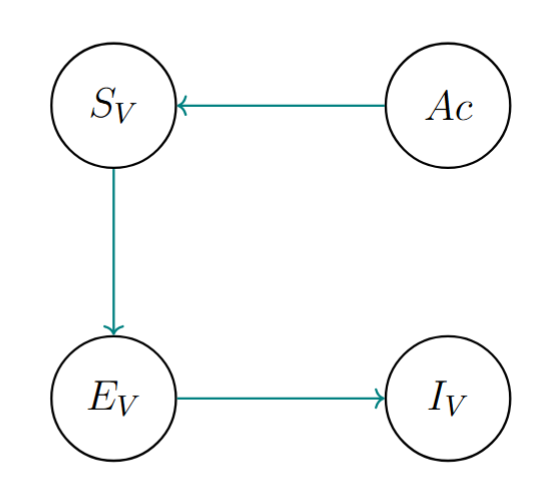

**Fig. 1** Source: Own elaboration.

The vector model divides mosquitoes into four compartments:

**1. **$S_V$**: Susceptible**

- It represents mosquitoes that can contract the disease because they are not infected.

- They transition to state **E (Exposed)** if they bite an infected person.

**2. **$E_V$**: Exposed**

- Mosquitoes that have come into contact with the virus or pathogen (by biting an infected person) but are not yet infectious due to the incubation period.

- After a certain period, these mosquitoes transition to state **I (Infected)**.

**3. **$I_V$**: Infected**

- Mosquitoes that are infected and capable of transmitting the disease to humans.

- They remain in this compartment until they die, after which they are no longer considered in the simulation.

**4. **$\textrm{Ac}$**: Aquatic**

- These are the eggs laid by mosquitoes.

**SEIR Graphs Associated with Humans**

For the human population, the associated graph follows a **SEIR** structure. In our simulation, the population is assumed to remain constant. The states **S (Susceptible), E (Exposed), I (Infected), and R (Recovered)** change over time, with time progressing in days.

Additionally, at the beginning of the simulation, the sum of all states must equal the initial population of humans. In fact, at any given time, the total sum of these states remains equal to the initial population.

 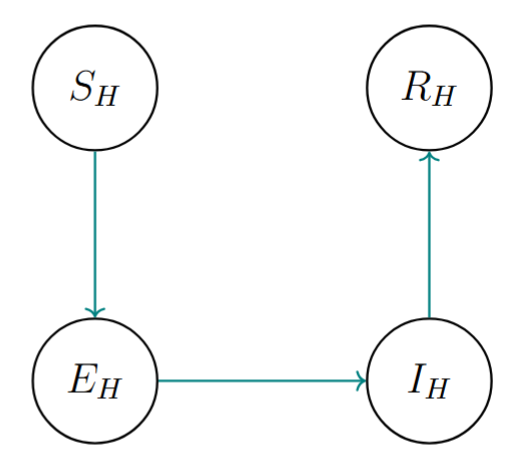

**Fig. 2 **Source: Own elaboration.

The human model divides the population into four compartments:

**1. **$S_H$**: Susceptible**

- Represents individuals who can contract the disease because they are neither infected nor immunized.

- They transition to state **E (Exposed)** if they are bitten by an infected mosquito.

**2. **$E_H$**: Exposed**

- Individuals who have been exposed to the virus or pathogen (bitten by an infected mosquito) but are not yet infectious due to the incubation period.

- After a certain period, these individuals transition to state **I (Infected)**.

**3. **$I_H$**: Infected**

- Individuals who are infected and capable of transmitting the disease to mosquitoes that bite them.

- They remain in this compartment for a specified period before recovering.

**4. **$R$**: Recovered**

- Individuals who have been infected but can no longer transmit the disease because they have developed immunity.

## Modeling Hypotheses

To accurately capture the dynamics of an epidemic between vectors and humans in a given territory, the following analysis and assumptions were considered:

- The phenomenon is modeled using time steps of one day.

- Broadly speaking, the epidemic spreads because both the vector carrying the disease and the human population coexist in the same territory. Through their interaction, the vector transmits the disease to individuals in the population, potentially leading to an epidemic.

In an **agent-based model**, three key aspects must be considered:

- **How do humans inhabit the territory?**

- **How do vectors inhabit the territory?**

- **How do humans and vectors interact?**

There are two key dynamics in the simulation:

- **Movement Dynamics**

- **Interaction Dynamics**

#### Map

A map, in its usual sense, is a polygon contained within the Cartesian plane, which can be represented in the unit square of the plane through a diffeomorphism. Additionally, color maps are of interest, where each position is associated with a color indicating, for example, population density or the probability of an event occurring.

In this context, a color map is a matrix that contains information about a set of points generated through simple random sampling of a rectangle $\left\lbrack 0,1\right\rbrack \times \left\lbrack 0,1\right\rbrack$ within the Cartesian plane. Each sampled point is associated with a color represented by a number between $0\;$and $1$, where $0$ corresponds to "blue" and $1$to "red." The rows of the matrix correspond to the number of points used for sampling. The first column represents the x-coordinate of these points, the second column represents the y-coordinate, and the third column contains the color associated with each point. This third column corresponds to an initial coloring; if the color distribution of the map changes over time, additional columns are added to the matrix to reflect the updated colors.

The advantage of representing a map with this reduced set of information lies in its computational efficiency. Additionally, when the color of a point that is not explicitly stored in the matrix is required, the simulator extrapolates its value using the colors of the nearest neighboring points.

#### Movement Dynamics

It refers to the behavioral patterns of both humans and mosquitoes within the defined territory. This dynamic answers the questions: **How do humans inhabit the territory?** and **How do vectors inhabit the territory?**

**Movement Dynamics in Humans**

Under the assumption of an initial human population $P_{H_0 }$ within the territory, **human movement dynamics** are simplified to the two main locations where individuals spend most of their time: **home and work**. This pattern remains constant throughout the entire simulation (i.e., across all days).

Additionally, **the time spent traveling between these two locations is disregarded**.

To generate the exact positions of **homes** and **workplaces** for the initial human population, the simulator uses **color-coded maps** that represent the **probability of location preference** for both residential and workplace areas.

- **Blue ("**$0$**")** indicates no preference for settling in that location.

- **Red ("**$1$**")** indicates a strong preference for that location.

Additionally, instead of generating these maps randomly, the model allows the user to **input predefined preference maps** for home and workplace locations.

**Movement Dynamics in Vectors**

The simulation also starts with a predetermined number of mosquitoes in the territory. However, their movement dynamics are **more complex** because they are influenced by **environmental factors**. The underlying hypothesis is that, **on a global scale, environmental conditions govern the movement dynamics of mosquitoes**.

All this environmental information is encoded in a **color-coded map**, where:

- **Red ("**$1$**")** represents the highest suitability for mosquito survival.

- **Blue ("**$0$**")** represents the lowest suitability for survival (mosquitoes cannot survive in these areas).

This **suitability map** is generated by the model. To increase realism, since **environmental conditions change over time**, the model **gradually updates the map**, driving mosquito movement dynamics.

Additionally, instead of generating these maps randomly, the user can **input a predefined series of mosquito suitability maps**, allowing the simulator to use real-world environmental data.

#### **Interaction Dynamics**

The interaction between **humans and mosquitoes** was designed to reflect their natural biological behavior. Based on biological studies of these species, the following key aspects are considered:

- **Only female mosquitoes bite humans** because they require blood proteins to produce eggs.

- **Mosquitoes have a limited flight range** (for dengue-carrying mosquitoes, the literature suggests a radius of **500 meters**).

- **Biting frequency varies by species**; for dengue-transmitting mosquitoes, studies indicate they bite **an average of 4 times per day**.

- **Disease transmission occurs through bites**: 

-     **Humans are infected** with a certain probability when bitten by an infected mosquito.

-     **Mosquitoes become infected** with a certain probability when biting an infected human.

All these factors are included in the model as **input parameters**.

Furthermore, this **infection dynamic** determines the **states in which mosquitoes and humans are classified**, shaping the overall epidemiological progression in the simulation.

#### **States:**

**SUSCEPTIBLE:** Individuals who are at risk of interacting with an infected individual. This category includes both humans and vectors.

**EXPOSED:** Individuals who have interacted with an infected individual and subsequently become infected. This category includes both humans and vectors.

**INFECTED:** Individuals who are actively carrying the disease. This category includes both humans and vectors.

**RECOVERED:** Individuals who have had the disease and recovered. **Only humans** can belong to this category, as mosquitoes die once they become infected.

#### **Object-Oriented Programming (OOP) for Modeling the Epidemiological Interaction Between Humans and Vectors**

The model is designed using **Object-Oriented Programming (OOP)**.

- There are **two child classes**:

- `sim_host`: Responsible for creating and managing objects that represent the **human population** and store their complete individual dynamics.

- `sim_vector`: Responsible for creating and managing objects that represent the **vector population** (mosquitoes) and store their complete individual dynamics.

- These child classes **inherit** from a **parent class** called `sim_scenario`, which provides the general framework for the simulation environment.

- Additionally, there is another class called `epidem_scenario`, which manages the **interaction between the two child classes**, facilitating the epidemiological dynamics between humans and vectors.

Now, imagine that you are part of the **initial population** living in a specific location within the defined territory. You are **susceptible** to infection by a vector.

Suppose a **new day begins**:

- You **travel from home to work**, which is located somewhere within the territory.

- While at work, you **might be within the range of an infected female mosquito**, which has an **average biting frequency of** `n_times` **per day**.

- If the mosquito **has not yet bitten that day **`n_times`, there is a **probability that it will bite you**.

- Since the mosquito is **infected**, there is another probability that **you become infected**.

- If this happens, you transition from being **Susceptible (S) to Exposed (E)**.

Later in the day:

- You **travel back home**.

- While at home, the same conditions apply: if you **are within the range of an infected mosquito**, and it has not yet bitten that day `n_times`, there is a **probability you will be bitten** and an additional probability of **getting infected**.

- If this happens, you again transition from **Susceptible (S) to Exposed (E)**.

After a **few days**, assuming you have been infected, you transition from the **Exposed (E) state to the Infected (I) state**.

Now, consider a mosquito egg located somewhere within the defined territory. If the **environmental conditions for survival** are favorable, after **two weeks**, the egg hatches into an **adult female mosquito**, entering its **adult stage** and becoming **susceptible to infection**.

At the **final stage of reproduction**, it is known from the literature that **human blood is required for egg-laying**. The mosquito then begins searching for a host. If a **human is within its flight range**, it will attempt to bite. If **multiple humans are available within range**, it will **randomly select the required number of hosts**, with the possibility of **biting the same individual multiple times**.

If at least **one of the bitten humans is infected**, the mosquito has a **probability of becoming infected** as well, transitioning from the **susceptible (S) state to the exposed (E) state**. After the incubation period, the mosquito **becomes infectious (I)** and can transmit the disease to other humans.

In the `epidem_scenario` class, there is a method called `epidem_cycle`, which simulates a **single day** in the **agent-based model** for humans and vectors. This method follows the sequence of events described earlier.**Summary of the **`epidem_cycle`** method:**

- **Start of the simulation day.**

- **Humans move from home to work.**

- **Vectors bite humans.**

- **Humans move from work back home.**

- **Vectors bite humans again.**

- **Infection process occurs in vectors** (newly exposed vectors transition to infected).

- **Infection process occurs in humans** (newly exposed humans transition to infected).

- **End of the simulation day.**

This cycle repeats for each day in the simulation, allowing the **epidemiological dynamics** to unfold over time.

## **Steps to Run a Simulation**

### **Step 1: Main Object with **`epidem_scenario`

The **first object** that needs to be created is the one generated by the `epidem_scenario` constructor. We will call this object `simulator`.

To use the `epidem_scenario` constructor, several parameters must be provided:

- `mu_a`: Mortality rate of the aquatic phase after the minimum waiting time (`delayM`).

- `mu_m`: Probability of mosquito death.

- `mu_h`: Probability of human replacement.

- `beta_hm`: Probability of disease transmission **from human to mosquito**.

- `beta_mh`: Probability of disease transmission **from mosquito to human**.

- `theta_m`: Probability of an exposed mosquito becoming infectious.

- `theta_am`: Probability of a mosquito egg becoming an adult female mosquito after the waiting time (`delayM`).

- `theta_h`: Probability of an exposed human becoming infectious after the waiting time (`delayH_ei`).

- `delta`: Number of eggs laid per day by a mosquito that has fed on human blood.

- `gamma`: Probability of an infected human recovering after the waiting time (`delayH_ir`).

- `K`: Carrying capacity (maximum population limit).

- `Z`: **Number of bites per mosquito** (average number of times a mosquito bites per day).

- `R`: **Mosquito habitat radius** (range of movement in kilometers).

- `ac_delay`: Delay (in days) before mosquito eggs hatch.

- `delayH_ei`: Minimum waiting time before **humans transition from exposed to infected**.

- `delayH_ir`: Minimum waiting time before **humans transition from infected to recovered**.

- `delayM`: Minimum waiting time before a mosquito **emerges as an adult** (related to `theta_am`).

This **epidemic scenario object (**`simulator`**)** will serve as the **core of the simulation**, handling the interactions between **humans and vectors** according to the specified parameters.

### **Step 2: Secondary Objects Associated with Vectors and Humans using **`create_Vpop`** and **`create_Hpop`

The next objects to be created are the **vector and human objects**, which are generated using the methods `create_Vpop` and `create_Hpop`.

Due to the way **Object-Oriented Programming (OOP)** works, these methods create a **new updated version** of the **simulator** object. It is recommended to **overwrite this new object in the existing simulator object** (in our case, `simulator`).

To use these methods, some additional parameters must be provided:

- `vec_pop`: Initial mosquito population.

- `host_pop`: Initial human population.

- `deformations_limit`: Parameter for generating maps (recommended values: **1, 2, or 3**).

- `msize`: Map size in kilometers.

- `ncentersH`: Number of maps to create for **humans**.

- `ncentersM`: Number of maps to create for **vectors**.

- `nreferencePoints`: Number of points used to generate maps. These points are sampled uniformly within the rectangle $\left\lbrack 0,1\right\rbrack \times \left\lbrack 0,1\right\rbrack$

- `minOccM`: Minimum percentage of occupation in the mosquito map.

- `maxOccM`: Maximum percentage of occupation in the mosquito map.

- `AlphaM`: Value that increases the **intensity of the color distribution in the mosquito map** (**recommended: a natural number greater than 1**). 

-     If `AlphaM=1`, the color distribution remains unchanged.

-     If `AlphaM=0`, the entire map is uniformly colored.

- `kindM`: Determines the mosquito reproduction paradigm: 

- `kindM=1`: Mosquitoes must **bite humans** to lay eggs.

- `kindM=0`: Mosquitoes lay eggs **without biting humans**.

- `minOccH`: Minimum percentage of occupation in the **human map**.

- `maxOccH`: Maximum percentage of occupation in the **human map**.

- `AlphaH`: Value that increases the **intensity of the color distribution in the human map** (**recommended: a natural number greater than 1**). 

-     If `AlphaH=1`, the color distribution remains unchanged.

-     If `AlphaH=0`, the entire map is uniformly colored.

**Note:**

If a **uniform simulation** is desired (i.e., where the movement dynamics of both vectors and humans are equally likely across all points, resulting in a uniformly colored map), use the following parameterization:

- **For mosquitoes/vectors** → `minOccM=1=maxOccM`

- **For humans** → `minOccH=1=maxOccH`

### **Step 3: Setting the Initial Conditions of the Populations with the **`set_initConds()`** Method**

The next step is to **set the initial conditions** for the **human and vector populations** using the method `set_initConds()`.

Again, we **update the **`simulator`** object** by overwriting it.

Two additional parameters must be provided:

- `propsH`: A **1×4 row vector** representing the **initial percentage distribution** of the human population across the following states:**[Susceptible, Exposed, Infected, Recovered]**.

- `propsV`: A **1×3 row vector** representing the **initial percentage distribution** of the vector population across the following states:**[Susceptible, Exposed, Infected]**.

**Note:**

The parameters `propsH` and `propsV` distribute the initial populations of **humans and mosquitoes**, respectively, according to the given proportions. **The sum of all entries must be 1** for the distribution to be valid.

### **Step 4: Iterating a Simulation Cycle with the **`epidem_cicle()`** Method**

At this point, a **simulation cycle** can be executed using the `epidem_cicle()` method.

Again, this **creates an updated version of the simulator object**, so it must be **overwritten**.**Simplified Algorithm for a Single Simulation Cycle:**

- **Humans move from the Home map to the Work map.**

- **Vectors bite humans.**

- **Humans move from the Work map back to the Home map.**

- **Vectors bite humans again.**

- **Infection in the vector population is recognized, and the number of individuals in vector states ("S, E, I") is updated.**

- **Infection in the human population is recognized, and the number of individuals in human states ("S, E, I, R") is updated.**

This process is repeated for each day in the simulation, allowing the **disease to spread and evolve dynamically** over time.

### **Step 5: Epidemiological Simulation with **`simulator()`

The `simulator()` method runs the **complete simulation** of the agent-based model.

Simulations can be **simple** or provide **additional information**, such as generating a **GIF**, extracting **map data**, or both.

Additionally, in any case, the simulation can be set to **update the vector map every **`time_step`** cycles**.

**Running a Simple Simulation**

To perform a **basic simulation**, use the `simulator()` function with the following configuration after completing **Step 3**:

- Where `num_ciclos` specifies the **number of cycles (days) of the simulation**.

#### Example 1: Simple Simulation

mu_a=    0.15;
mu_m=    0.38;
mu_h=   0.02;
beta_hm= 0.58;
beta_mh= 0.3;
theta_m= 0.9;
theta_am=0.89;
theta_h= 0.9;
delta=          8;
gamma=   0.05;
K=2e3;
Z=              4;
R=              0.5;
ac_delay=       14;
delayH_ei=      2;
delayH_ir=      2;
delayM=         2;
% The created object is called "sim1". 
sim1=epidem_scenario(mu_a,mu_m,mu_h,beta_hm,beta_mh,theta_m, ...
    theta_am,theta_h,delta,gamma,K,Z,R,ac_delay,delayH_ei,delayH_ir,delayM);

%Map and population params
vec_pop=100;
host_pop=1000;
deformations_limit=1;
msize=400;
ncentersH=2;
ncentersM=2;
nreferencePoints=rand(5000,2);
%%%% params
minOccM=0.5; 
maxOccM=0.5;
alphaM=2;
kindM=2;
minOccH=0.5;
maxOccH=0.5;
alphaH=1;
% Creates the "Vectors" object, which stores the movement  
% and interaction dynamics of mosquitoes/vectors. 
sim1=sim1.create_Vpop(vec_pop,nreferencePoints, ...
    msize,ncentersM,deformations_limit,minOccM,maxOccM,alphaM,kindM);
% Creates the "Hosts" object, which stores the movement  
% and interaction dynamics of humans. 
sim1=sim1.create_Hpop(host_pop,nreferencePoints, ...
    msize,ncentersH,deformations_limit,ncentersH,minOccH,maxOccH,alphaH)

sim1 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: []
     numCicles: 1
    matrix_MAP: []



propsH = [0.9, 0.1 , 0, 0];
propsV = [0.8, 0.2, 0];
% This generates the initial conditions of the simulation.
sim1=sim1.set_initConds(propsH,propsV); 

num_ciclos=50; % number of cycles (days) of the simulation.
sim1=sim1.simulator(num_ciclos)

sim1 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: [9×52 double]
     numCicles: 1
    matrix_MAP: []


#### **Changing the Vector Map Using **`simulator() & ``change_vectorMap(time_step)`

In **Step 4**, the simulation cycles operate using a **color map** created by the simulator when the `create_Vpop()` method is applied. This map **determines the movement dynamics of the vector population**.

When **Step 4 is repeated**, the simulation continues using the **same color map** unless modified.

The function `change_vectorMap(time_step)` updates the vector maps over the next `time_step` cycles.

**How It Works:**

- **A new map is created**, replacing the previous one **gradually** over the next `time_step` simulation cycles.

- This ensures **continuity in vector movement dynamics**, rather than an abrupt change.

- After these iterations, **Step 4 will use the updated map**.

**Parameter Restriction:**

- `time_step` must be a **positive natural number**.

To run a **simple simulation** where the **vector map updates periodically**, add the `time_step` parameter at the end of the `simulator()` method.

Under this configuration, the `simulator()` method internally uses `change_vectorMap(time_step)` to update the vector map throughout the simulation.

In **Example 1**, the following line:

Can be rewritten as:

This ensures that the **vector map updates every **`time_step`** cycles** during the simulation.

### **Step 6: Extracting State Information for Visualization Using **`graphicSummary()`** and Time Series Analysis**

The `graphicSummary()` method allows for extracting and visualizing the **evolution of epidemiological states** over time. Additionally, time series data can be extracted for further analysis.

To **plot the time series** of each epidemiological state, run the following code after completing **Step 5**:

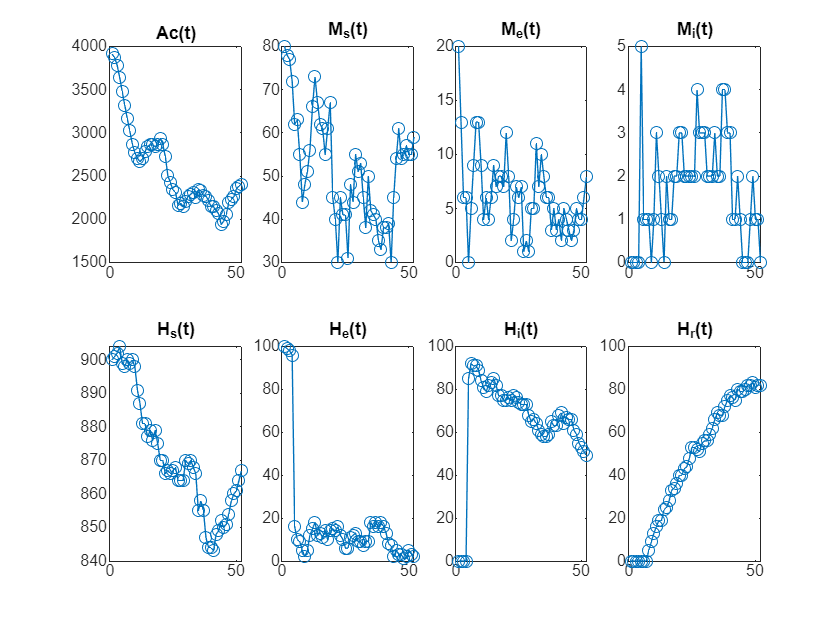

time_series = sim1.graphicSummary();

This extracts and visualizes the **evolution of each state** over the simulation period.

The graphs correspond to the **time series** of:

- $\mathrm{Ac}\left(t\right)$: *(In Fig. 1, this represents the population of node *$\mathrm{Ac}$* over the simulation time)***.**

- ${\mathrm{M}}_{\mathrm{s}} \left(\mathrm{t}\right)$: *(In Fig. 1, this represents the population of node *$S_V$* over the simulation time)***.**

- ${\mathrm{M}}_{\mathrm{e}} \left(\mathrm{t}\right)$: *(In Fig. 1, this represents the population of node *$E_V$* over the simulation time).*

- ${\mathrm{M}}_{\mathrm{i}} \left(\mathrm{t}\right)$: *(In Fig. 1, this represents the population of node *$I_V$ *over the simulation time).*

- ${\mathrm{H}}_{\mathrm{s}} \left(\mathrm{t}\right)$: *(In Fig. 2, this represents the population of node *$S_H$* over the simulation time).*

- ${\mathrm{H}}_{\mathrm{e}} \left(\mathrm{t}\right)$: *(In Fig. 2, this represents the population of node *$E_H$* over the simulation time).*

- ${\mathrm{H}}_{\mathrm{i}} \left(\mathrm{t}\right)$: *(In Fig. 2, this represents the population of node *$I_H$* over the simulation time).*

- ${\mathrm{H}}_{\mathrm{r}} \left(\mathrm{t}\right)$: *(In Fig. 2, this represents the population of node *$R_H$* over the simulation time).*

`summary` is possibly the **most useful attribute/property** of the `epidem_scenario` class. This property is a **historical matrix** with **9 rows**, where each cycle of the simulation **adds a new column**. The **number of columns** is equal to the **number of cycles + 1**, and it **updates dynamically** with each iteration.

**Structure of the **`summary`** Matrix:**

**Mosquito Population (First 4 Rows)**

Each row corresponds to the **number of individuals in a given state at the end of each cycle**:

- **Number of mosquito eggs laid** during a specific cycle.

- **Number of susceptible mosquitoes** at the end of a specific cycle.

- **Number of exposed mosquitoes** at the end of a specific cycle.

- **Number of infected mosquitoes** at the end of a specific cycle.

(*In Fig. 1, these states correspond to the respective nodes in the vector model.*)

**Human Population (Next 4 Rows)**

Each row corresponds to the **number of humans in a given state at the end of each cycle**:

        5. **Number of susceptible humans** at the end of a specific cycle.

        6. **Number of exposed humans** at the end of a specific cycle.

        7. **Number of infected humans** at the end of a specific cycle.

        8. **Number of recovered humans** at the end of a specific cycle.

        (*In Fig. 2, these states correspond to the respective nodes in the human model.*)

**Cumulative flow of Individuals Between States **$E_H$ **and **$I_H$ **(Last Row)**

         9. **Cumulative sum of individuals transitioning from state **$E_H$ **to state **$I_H$  over time.

(*In Fig. 2, let us define *$f\left(t\right)$* the flow of individuals moving from state *$E_H$* to state *$I_H$ *at time ****t****.)*

 Then, this row corresponds to: $\sum_{i=0}^t f\left(i\right)$

For clarity, the matrix described above looks like this:

Let  ${\textrm{Ac}\left(t\right)\;;\;S}_v \left(t\right)\;;E_{v\;} \left(t\right)\;;I_v \left(t\right)$${;\;S}_H \;;E_H \;;I_H \;;R_H \;\;$ be the population size found in the respective states over time.

$\left\lbrack \begin{array}{cccc}
\textrm{Ac}\left(0\right)\; & \textrm{Ac}\left(1\right)\;\;\; & \ldotp \ldotp \ldotp  & \textrm{Ac}\left(t\right)\;\\
S_v \;\left(0\right) & S_v \left(1\right) & \ldotp \ldotp \ldotp  & S_v \left(t\right)\;\;\\
E_v \;\left(0\right) & E_v \left(1\right) & \ldotp \ldotp \ldotp  & E_v \;\left(t\right)\\
I_v \;\left(0\right) & I_v \;\left(1\right) & \ldotp \ldotp \ldotp  & I_v \;\left(t\right)\\
S_{H\;} \left(0\right) & S_{H\;} \left(1\right) & \ldotp \ldotp \ldotp  & S_{H\;} \left(t\right)\\
E_H \;\left(0\right) & E_H \left(1\right) & \ldotp \ldotp \ldotp  & E_H \;\left(t\right)\\
I_H \;\left(0\right) & I_H \;\left(1\right) & \ldotp \ldotp \ldotp  & I_H \;\left(t\right)\\
R_{H\;} \left(0\right) & R_{H\;} \left(1\right) & \ldotp \ldotp \ldotp  & R_{H\;} \left(t\right)\\
f\left(0\right)=0 & f\left(0\right)+f\left(1\right) & \ldotp \ldotp \ldotp  & \sum_{i=0}^t f\left(i\right)
\end{array}\right\rbrack$.

Additionally, if a **time series of infected humans** is needed, extract the data from the **ninth row** using the following steps:

Hi=sim1.Summary(9,:);% Extracts the accumulated H_i  
% This could be useful if a time series of infected humans (H_i) is needed.

### Step 7: Simulation Including Color Map Information for Vectors Over Time and Human Maps

In this context, a color map is a matrix that contains information about a set of points generated through simple random sampling of a rectangle $\left\lbrack 0,1\right\rbrack \times \left\lbrack 0,1\right\rbrack$ within the Cartesian plane. Each sampled point is associated with a color represented by a number between 0 and 1, where 0 corresponds to "blue" and 1 to "red." 

Humans have two associated color maps: one that determines their **homes** and another that determines their **workplaces**.

Vectors have a single color map that governs their **movement dynamics**. This map can change over the course of the iterations. When the map changes, it means that the **color assigned to each sampled point is updated** during the current iteration.

To ensure that this information is stored by the simulator, use the `simulator()` function with the following configuration:

- `num_ciclos`: Specifies the **number of cycles (days) of the simulation**.

- `extract_step`: Defines the **frequency at which the vector map coloring is captured**.

#### Example 2: Simulation with Map Extraction

%    mu_a=    0.15;
% mu_m=    0.38;
% mu_h=   0.02;
% beta_hm= 0.58;
% beta_mh= 0.3;
% theta_m= 0.9;
% theta_am=0.89;
% theta_h= 0.9;
% delta=          8;
% gamma=   0.05;
% K=2e3;
% Z=              4;
% R=              0.5;
% ac_delay=       14;
% delayH_ei=      2;
% delayH_ir=      2;
% delayM=         2;

% The created object is named sim2.  
sim2=epidem_scenario(mu_a,mu_m,mu_h,beta_hm,beta_mh,theta_m, ...
    theta_am,theta_h,delta,gamma,K,Z,R,ac_delay,delayH_ei,delayH_ir,delayM);

%Map and population params
% vec_pop=100;
% host_pop=1000;
% deformations_limit=1;
% msize=400;
% ncentersH=2;
% ncentersM=2;
% nreferencePoints=rand(5000,2);
% %%%% params
% minOccM=0.5; 
% maxOccM=0.5;
% alphaM=2;
% kindM=2;
% minOccH=0.5;
% maxOccH=0.5;
% alphaH=1;

% Creates the "Vectors" object, which stores the movement  
% and interaction dynamics of mosquitoes/vectors.
sim2=sim2.create_Vpop(vec_pop,nreferencePoints, ...
    msize,ncentersM,deformations_limit,minOccM,maxOccM,alphaM,kindM);
% Creates the "Hosts" object, which stores the movement  
% and interaction dynamics of humans.
sim2=sim2.create_Hpop(host_pop,nreferencePoints, ...
    msize,ncentersH,deformations_limit,ncentersH,minOccH,maxOccH,alphaH)

sim2 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: []
     numCicles: 1
    matrix_MAP: []



% propsH = [0.9, 0.1 , 0, 0];
% propsV = [1, 0, 0];

% This generates the initial conditions of the simulation.
sim2=sim2.set_initConds(propsH,propsV); 

% num_ciclos=100; % % number of cycles (days) of the simulation.
extract_step=7; % The frequency at which the vector map coloring is captured.  
sim2=sim2.simulator(num_ciclos,extract_step,[],[]) 

sim2 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: [9×52 double]
     numCicles: 1
    matrix_MAP: {[5000×3 double]  [5000×3 double]  [5000×11 double]}


MAP_cell2=sim2.matrix_MAP % A cell that stores the human Home map, human Work map, and vector map.  

MAP_cell2 = 1×3 cell array
    {5000×3 double}    {5000×3 double}    {5000×11 double}


Additionally, to run a **simulation with map extraction** where the **vector map changes periodically**, replace the final `[]` parameter with `time_step` in the `simulator()` method.

In **Example 2**, the following line:

Can be rewritten as:

**Note: **`time_step` must be a **positive natural number**.

### Step 8: Simulation Including a GIF Using the `get_graphics()` Method

The `get_graphics()` method belongs to the `epidem_scenario` class. This method **visually represents** various aspects of the simulation by generating **eight different plots**.

**Generated Graphs:**

- **Humans Home**

- Displays the **exact residential locations** of all individuals in the human population.

- Identifies their **epidemiological state** using colors: 

- **Green** → Susceptible ("S")

- **Orange** → Exposed ("E")

- **Red** → Infected ("I")

- **Blue** → Recovered ("R")

- This movement dynamic is determined by the **human color map ("Host")**, which is visualized in the **Host + Work** plot.

- **Humans Work**

- Displays the **work locations** of all individuals in the human population.

- Identifies epidemiological states using the same color scheme as the **Humans Home** graph.

- Unlike **residences**, work locations are **not fixed**; instead, the **"Work" color map** is used to guide individuals toward **preferred locations**.

- This design captures a **more realistic social dynamic**, where individuals always return home, but work is **not the only inhabited location**.

- **Vector Map**

- Represents the **color map** that determines the **movement dynamics of vectors**.

- This **suitability map** is constructed based on **environmental information** for the analyzed region.

- Since this map can **change over time**, these updates are illustrated in the GIF.

- **Host Home + Work**

- Merges the two **human movement maps** (Home & Work).

- These maps **do not change over time**, meaning they remain constant across all simulation cycles.

- **Vectors**

- Displays the **location of mosquitoes** on a **specific simulation day**.

- Identifies epidemiological states using colors: 

- **Green** → Susceptible ("S")

- **Orange** → Exposed ("E")

- **Red** → Infected ("I")

- As **vector maps change**, this affects mosquito distribution in the simulation.

- **Aquatic**

- Displays **all live mosquito eggs** at a given simulation moment.

- Each **egg** is represented by an **orange dot**.

- **Newly hatched eggs** are shown as **green dots**, representing the emergence of **susceptible mosquitoes**.

- **History of Vector States**

- Plots the **historical trends** of mosquito states over time: 

- **S(t)** → Susceptible

- **E(t)** → Exposed

- **I(t)** → Infected

- **A(t)** → Aquatic *(corresponds to the ****Ac**** node in Fig. 1)*.

- **History of Human States**

- Plots the **historical trends** of human states over time: 

- **S(t)** → Susceptible

- **E(t)** → Exposed

- **I(t)** → Infected

- **R(t)** → Recovered

**Example of a GIF Frame:**

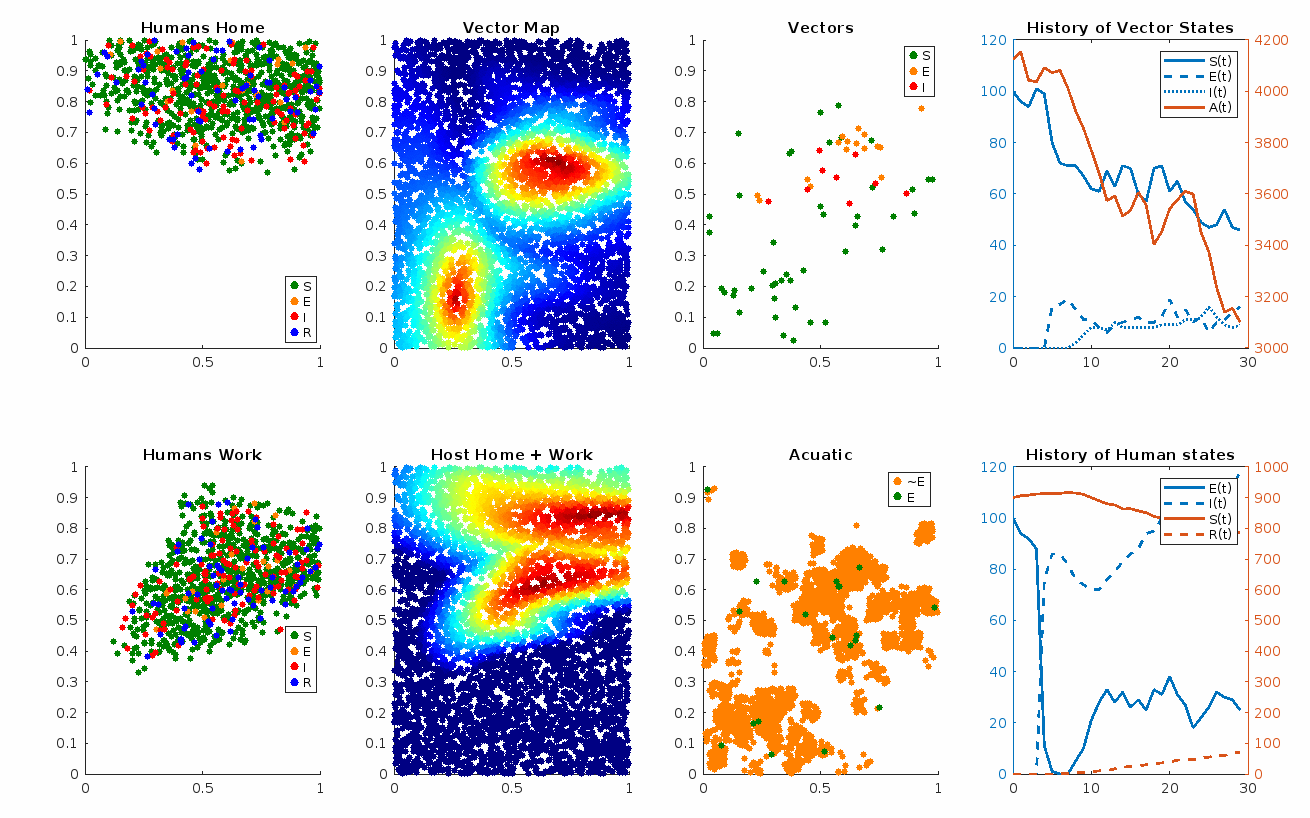

**Fig. 3 **Source: Own elaboration.

With the `get_graphics()` method, it is possible to create a **GIF** that visually represents the **entire simulation's evolution**, including:

- **Color maps**

- **Movement dynamics** of both vectors and humans

- **Interaction dynamics** between vectors and humans

- **State history trends** for both populations

To run a **simulation with GIF generation**, use the `simulator()` function with the following configuration after completing **Step 3**:

- `num_ciclos`: Specifies the **number of cycles (days) of the simulation**.

- `'nameGIF.gif'`: Defines the **name of the GIF file**, including its extension.

Under this configuration, the `simulator()` method internally uses `get_graphics()` to generate and save the GIF during the simulation.

**Note: **The package **must be imported** before running the code:

🔗 [MATLAB GIF package](https://www.mathworks.com/matlabcentral/fileexchange/63239-gif)

#### Example 3: Simulation with GIF Generation

%    mu_a=    0.15;
% mu_m=    0.38;
% mu_h=   0.02;
% beta_hm= 0.58;
% beta_mh= 0.3;
% theta_m= 0.9;
% theta_am=0.89;
% theta_h= 0.9;
% delta=          8;
% gamma=   0.05;
% K=2e3;
% Z=              4;
% R=              0.5;
% ac_delay=       14;
% delayH_ei=      2;
% delayH_ir=      2;
% delayM=         2;

% The created object is named sim3.  
sim3=epidem_scenario(mu_a,mu_m,mu_h,beta_hm,beta_mh,theta_m, ...
    theta_am,theta_h,delta,gamma,K,Z,R,ac_delay,delayH_ei,delayH_ir,delayM);

% %Map and population params
% vec_pop=100;
% host_pop=1000;
% deformations_limit=1;
% msize=400;
% ncentersH=2;
% ncentersM=2;
% nreferencePoints=rand(5000,2);
% %%%% params
% minOccM=0.5; 
% maxOccM=0.5;
% alphaM=2;
% kindM=2;
% minOccH=0.5;
% maxOccH=0.5;
% alphaH=1;

% Creates the "Vectors" object, which stores the movement  
% and interaction dynamics of mosquitoes/vectors.
sim3=sim3.create_Vpop(vec_pop,nreferencePoints, ...
    msize,ncentersM,deformations_limit,minOccM,maxOccM,alphaM,kindM);

% Creates the "Hosts" object, which stores the movement  
% and interaction dynamics of humans.
sim3=sim3.create_Hpop(host_pop,nreferencePoints, ...
    msize,ncentersH,deformations_limit,ncentersH,minOccH,maxOccH,alphaH)

sim3 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: []
     numCicles: 1
    matrix_MAP: []


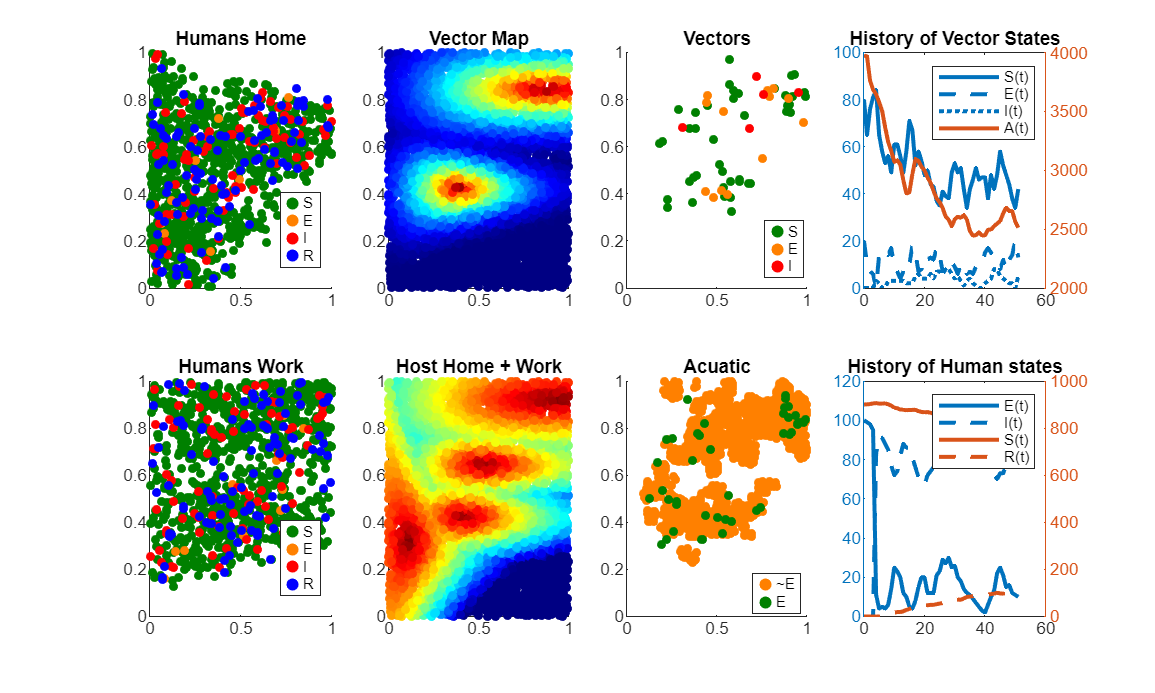

sim3 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: [9×52 double]
     numCicles: 1
    matrix_MAP: []



% propsH = [0.9, 0.1 , 0, 0];
% propsV = [1, 0, 0];

% This generates the initial conditions of the simulation.
sim3=sim3.set_initConds(propsH,propsV); 

%num_ciclos=100; % Days or simulation cycles.  
nameGIF='nameGIF3.gif'; % Specifies the name of the GIF, including its extension.  
sim3=sim3.simulator(num_ciclos,[],nameGIF,[]) 

Additionally, to run a **simulation with GIF generation** where the **vector map changes periodically**, replace the final `[]` parameter with `time_step` in the `simulator()` method.

In **Example 3**, the following line:

Can be rewritten as:

**Note: **`time_step` must be a **positive natural number**.

#### Example 4: Simulation with GIF and Vector Map Updates

%    mu_a=    0.15;
% mu_m=    0.38;
% mu_h=   0.02;
% beta_hm= 0.58;
% beta_mh= 0.3;
% theta_m= 0.9;
% theta_am=0.89;
% theta_h= 0.9;
% delta=          8;
% gamma=   0.05;
% K=2e3;
% Z=              4;
% R=              0.5;
% ac_delay=       14;
% delayH_ei=      2;
% delayH_ir=      2;
% delayM=         2;

% The created object is named sim4.  
sim4=epidem_scenario(mu_a,mu_m,mu_h,beta_hm,beta_mh,theta_m, ...
    theta_am,theta_h,delta,gamma,K,Z,R,ac_delay,delayH_ei,delayH_ir,delayM);

% %Map and population params
% vec_pop=100;
% host_pop=1000;
% deformations_limit=1;
% msize=400;
% ncentersH=2;
% ncentersM=2;
% nreferencePoints=rand(5000,2);
% %%%% params
% minOccM=0.5; 
% maxOccM=0.5;
% alphaM=2;
% kindM=2;
% minOccH=0.5;
% maxOccH=0.5;
% alphaH=1;

% Creates the "Vectors" object, which stores the movement  
% and interaction dynamics of mosquitoes/vectors. 
sim4=sim4.create_Vpop(vec_pop,nreferencePoints, ...
    msize,ncentersM,deformations_limit,minOccM,maxOccM,alphaM,kindM);

% Creates the "Hosts" object, which stores the movement  
% and interaction dynamics of humans. 
sim4=sim4.create_Hpop(host_pop,nreferencePoints, ...
    msize,ncentersH,deformations_limit,ncentersH,minOccH,maxOccH,alphaH)

sim4 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: []
     numCicles: 1
    matrix_MAP: []


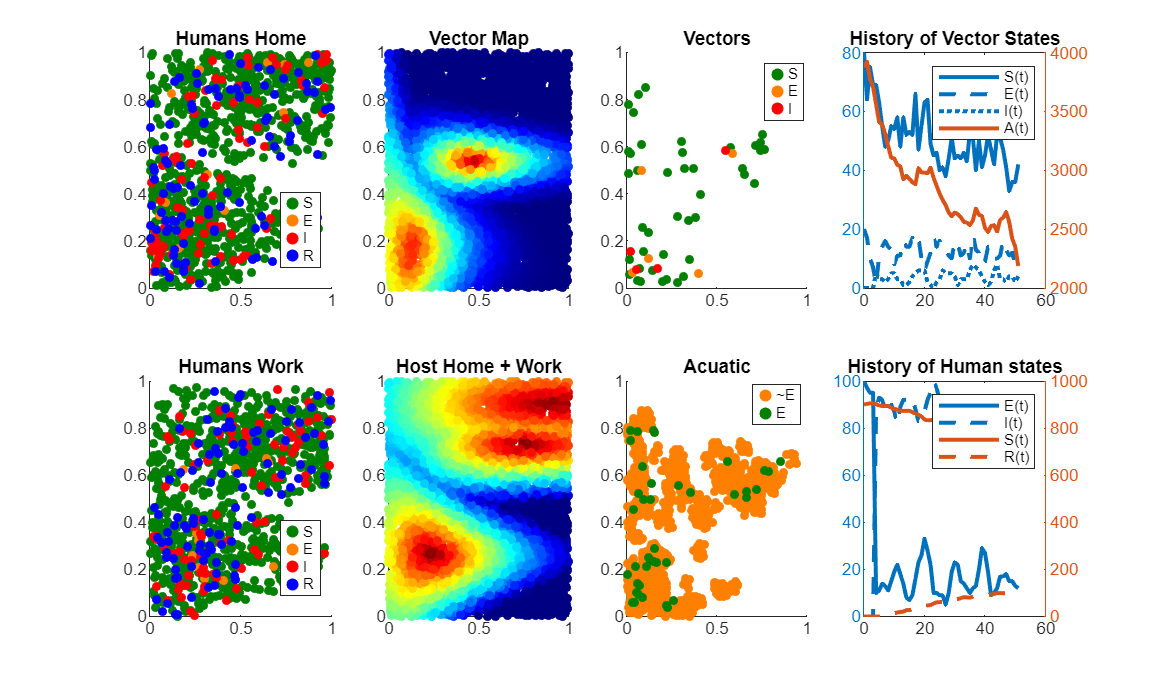

sim4 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: [9×52 double]
     numCicles: 13
    matrix_MAP: []



% propsH = [0.9, 0.1 , 0, 0];
% propsV = [1, 0, 0];
% This generates the initial conditions of the simulation.
sim4=sim4.set_initConds(propsH,propsV); 

% num_ciclos=100; % Days or simulation cycles.  
nameGIF='nameGIF4.gif'; % Specifies the name of the GIF, including its extension.  
time_step=20; % The frequency at which the vector map changes.  
sim4=sim4.simulator(num_ciclos,[],nameGIF,time_step) 

### **Step 9: Simulation Including GIF and Map Extraction**

This is the **most comprehensive** configuration for the simulator.

To run a **simulation that generates a GIF while extracting map data**, use the `simulator()` function with the following configuration after completing **Step 3**:

- `num_ciclos`: Number of simulation cycles (days).

- `extract_step`: Frequency at which the **vector map coloring** is captured.

- `'nameGIF.gif'`: Name of the GIF file, including its extension.

**Note: **The **GIF package** must be imported before running the simulation:

🔗 [MATLAB GIF Package](https://www.mathworks.com/matlabcentral/fileexchange/63239-gif)

**Example 5: Simulation with GIF and Map Extraction**

%    mu_a=    0.15;
% mu_m=    0.38;
% mu_h=   0.02;
% beta_hm= 0.58;
% beta_mh= 0.3;
% theta_m= 0.9;
% theta_am=0.89;
% theta_h= 0.9;
% delta=          8;
% gamma=   0.05;
% K=2e3;
% Z=              4;
% R=              0.5;
% ac_delay=       14;
% delayH_ei=      2;
% delayH_ir=      2;
% delayM=         2;

% The created object is named simu5.  
sim5=epidem_scenario(mu_a,mu_m,mu_h,beta_hm,beta_mh,theta_m, ...
    theta_am,theta_h,delta,gamma,K,Z,R,ac_delay,delayH_ei,delayH_ir,delayM);

% %Map and population params
% vec_pop=100;
% host_pop=1000;
% deformations_limit=1;
% msize=400;
% ncentersH=2;
% ncentersM=2;
% nreferencePoints=rand(5000,2);
% %%%% params
% minOccM=0.5; 
% maxOccM=0.5;
% alphaM=2;
% kindM=2;
% minOccH=0.5;
% maxOccH=0.5;
% alphaH=1;

% Creates the "Vectors" object, which stores the movement  
% and interaction dynamics of mosquitoes/vectors. 
sim5=sim5.create_Vpop(vec_pop,nreferencePoints, ...
    msize,ncentersM,deformations_limit,minOccM,maxOccM,alphaM,kindM);

% Creates the "Hosts" object, which stores the movement  
% and interaction dynamics of humans. 
sim5=sim5.create_Hpop(host_pop,nreferencePoints, ...
    msize,ncentersH,deformations_limit,ncentersH,minOccH,maxOccH,alphaH)

sim5 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: []
     numCicles: 1
    matrix_MAP: []


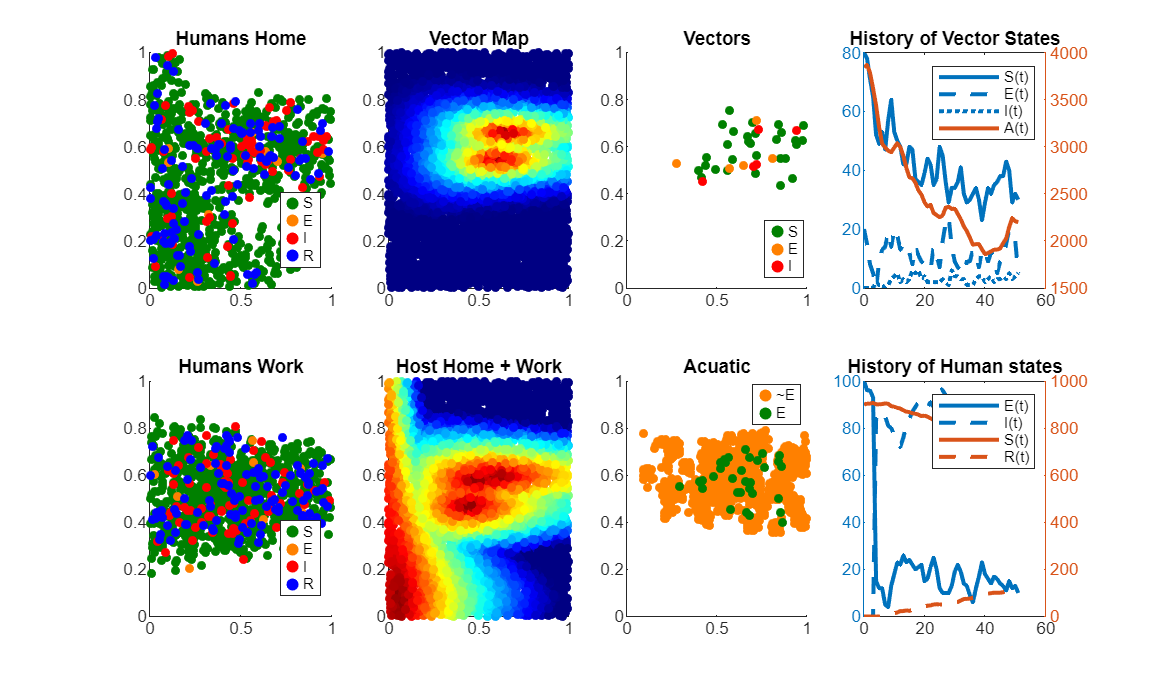

sim5 =   epidem_scenario with properties:

         parsV: [1×1 struct]
         parsH: [1×1 struct]
       Vectors: [1×1 sim_vector]
         Hosts: [1×1 sim_host]
       Summary: [9×52 double]
     numCicles: 1
    matrix_MAP: {[5000×3 double]  [5000×3 double]  [5000×11 double]}



% propsH = [0.9, 0.1 , 0, 0];
% propsV = [1, 0, 0];

% This generates the initial conditions of the simulation.
sim5=sim5.set_initConds(propsH,propsV); 

% num_ciclos=100; % Days or simulation cycles.  
extract_step=7; % The frequency at which the vector map coloring is captured.  
nameGIF='nameGIF5.gif'; % Specifies the name of the GIF, including its extension.  

sim5=sim5.simulator(num_ciclos,extract_step,nameGIF,[])  

MAP_cell5=sim5.matrix_MAP % A cell that stores the human Home map, human Work map, and vector map.  

MAP_cell5 = 1×3 cell array
    {5000×3 double}    {5000×3 double}    {5000×11 double}


Additionally, to run a **simulation with GIF generation and map extraction** where the **vector map changes periodically**, replace the final `[]` parameter with `time_step` in the `simulator()` method.

In **Example 5**, the following line:

Can be rewritten as:

**Note: **`time_step` must be a **positive natural number**.